# Lab 3 - Mariotte Bottle

clear;
clc;

## Set measurements data

bottle = 6

bottle = 6

hole = 0.4

hole = 0.4000


areaBottle = pi * ((bottle/2)^2)

areaBottle = 28.2743

areaHole = pi * ((hole/2)^2)

areaHole = 0.1257


areas = areaBottle / areaHole

areas = 225.0000

## Load files

v1 = 'https://raw.githubusercontent.com/cararm4073/tec-archive/refs/heads/main/university/EF26/F1008/Lab3/video1.csv'

v1 = 'https://raw.githubusercontent.com/cararm4073/tec-archive/refs/heads/main/university/EF26/F1008/Lab3/video1.csv'

v2 = 'https://raw.githubusercontent.com/cararm4073/tec-archive/refs/heads/main/university/EF26/F1008/Lab3/video2.csv'

v2 = 'https://raw.githubusercontent.com/cararm4073/tec-archive/refs/heads/main/university/EF26/F1008/Lab3/video2.csv'

v3 = 'https://raw.githubusercontent.com/cararm4073/tec-archive/refs/heads/main/university/EF26/F1008/Lab3/video3.csv'

v3 = 'https://raw.githubusercontent.com/cararm4073/tec-archive/refs/heads/main/university/EF26/F1008/Lab3/video3.csv'

v4 = 'https://raw.githubusercontent.com/cararm4073/tec-archive/refs/heads/main/university/EF26/F1008/Lab3/video4.csv'

v4 = 'https://raw.githubusercontent.com/cararm4073/tec-archive/refs/heads/main/university/EF26/F1008/Lab3/video4.csv'

v5 = 'https://raw.githubusercontent.com/cararm4073/tec-archive/refs/heads/main/university/EF26/F1008/Lab3/video5.csv'

v5 = 'https://raw.githubusercontent.com/cararm4073/tec-archive/refs/heads/main/university/EF26/F1008/Lab3/video5.csv'


data1 = rmmissing(readtable(v1), 'DataVariables', {'t','y'}); %Without extra heading from tracker
data2 = rmmissing(readtable(v2, 'NumHeaderLines', 1), 'DataVariables',{'t','y'} ); %Extra header or row from tracker, delete it and rename for ease. Happens with files 2 3 and 5
data3 = rmmissing(readtable(v3, 'NumHeaderLines', 1), 'DataVariables',{'t','y'} );
data4 = rmmissing(readtable(v4), 'DataVariables', {'t','y'}); 

data5 = rmmissing(readtable(v5, 'NumHeaderLines', 1), 'DataVariables',{'t','y'} );

## Load data

t1 = data1.t;
y1 = data1.y;

t2 = data2.t;
y2 = data2.y;

t3 = data3.t;
y3 = data3.y;

t4 = data4.t;
y4 = data4.y;

t5 = data5.t;
y5 = data5.y;

## Maths

With the derivatives for height (y) respecto to time, obtain the velocity in which the water decreases

vLevel1 = -gradient(y1, t1)

vLevel1 =          0
    0.0667
    0.1322
    0.0656
    0.0662
    0.0661
    0.0661
    0.1323
    0.0661
         0
         0
         0
    0.0661
    0.1317
    0.1317


vLevel2 = -gradient(y2, t2)

vLevel2 =     0.1632
    0.1844
    0.1731
    0.1569
    0.1952
    0.1900
    0.1518
    0.1408
    0.1519
    0.1460
    0.1100
    0.0910
    0.1189
    0.1320
    0.0998


vLevel3 = -gradient(y3, t3)

vLevel3 =          0
         0
         0
         0
    0.0285
    0.0357
    0.0166
    0.0285
    0.0522
    0.1261
    0.2093
    0.2641
    0.3673
    0.3031
    0.1928


vLevel4 = -gradient(y4, t4)

vLevel4 =     0.0885
    0.1028
    0.1328
    0.2061
    0.1913
    0.1478
    0.2061
    0.1470
    0.0878
    0.0885
    0.0743
    0.0735
    0.0292
         0
    0.0293


vLevel5 = -gradient(y5, t5)

vLevel5 =          0
         0
         0
    0.0083
    0.1168
    0.2585
    0.3666
    0.2588
    0.1335
    0.1417
    0.1005
    0.1583
    0.1747
    0.1170
    0.1508


Output velocities or efflix velocities

vOut1 = vLevel1 * areas

vOut1 =          0
   15.0088
   29.7542
   14.7541
   14.8858
   14.8771
   14.8771
   29.7717
   14.8771
         0
         0
         0
   14.8771
   29.6226
   29.6399


vOut2 = vLevel2 * areas

vOut2 =    36.7245
   41.4865
   38.9582
   35.3006
   43.9105
   42.7550
   34.1459
   31.6716
   34.1709
   32.8503
   24.7434
   20.4696
   26.7425
   29.6921
   22.4505


vOut3 = vLevel3 * areas

vOut3 =          0
         0
         0
         0
    6.4232
    8.0284
    3.7427
    6.4225
   11.7378
   28.3645
   47.0930
   59.4149
   82.6462
   68.1920
   43.3796


vOut4 = vLevel4 * areas

vOut4 =    19.9025
   23.1245
   29.8762
   46.3831
   43.0420
   33.2521
   46.3831
   33.0833
   19.7487
   19.9025
   16.7104
   16.5416
    6.5780
         0
    6.5829


vOut5 = vLevel5 * areas

vOut5 =          0
         0
         0
    1.8756
   26.2894
   58.1709
   82.4775
   58.2333
   30.0450
   31.8778
   22.6182
   35.6152
   39.2991
   26.3316
   33.9272


## Plotting

### Case 1 

Water level velocity vs time

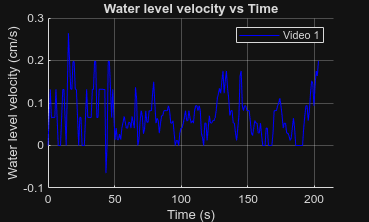

figure();
hold on;
plot(t1, vLevel1, 'b-', 'DisplayName', 'Video 1');
title('Water level velocity vs Time');
xlabel("Time (s)");
xlim([0,215]);
ylabel("Water level velocity (cm/s)");
legend();
grid on;
hold off;

Output velocity vs time

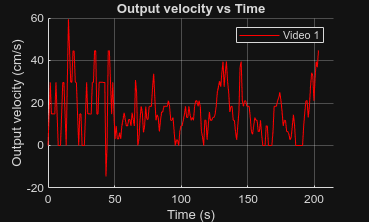

figure();
hold on;
plot(t1, vOut1, 'r-', 'DisplayName', 'Video 1');
title('Output velocity vs Time');
xlabel("Time (s)");
xlim([0,215]);
ylabel("Output velocity (cm/s)");
legend();
grid on;
hold off;

### Case 2

Water level velocity vs time

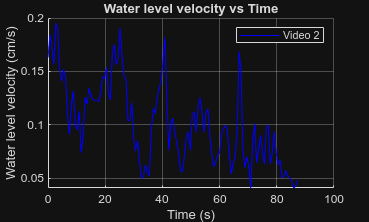

figure();
hold on;
plot(t2, vLevel2, 'b-', 'DisplayName', 'Video 2');
title('Water level velocity vs Time');
xlabel("Time (s)");
xlim([0,100]);
ylabel("Water level velocity (cm/s)");
legend();
grid on;
hold off;

Output velocity vs time

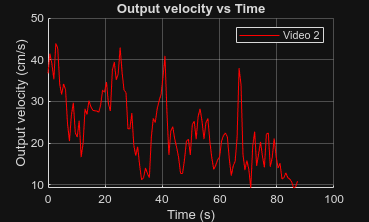

figure();
hold on;
plot(t2, vOut2, 'r-', 'DisplayName', 'Video 2');
title('Output velocity vs Time');
xlabel("Time (s)");
xlim([0,100]);
ylabel("Output velocity (cm/s)");
legend();s
grid on;
hold off;

### Case 3

Water level velocity vs time

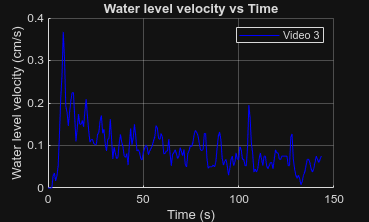

figure();
hold on;
plot(t3, vLevel3, 'b-', 'DisplayName', 'Video 3');
title('Water level velocity vs Time');
xlabel("Time (s)");
xlim([0,150]);
ylabel("Water level velocity (cm/s)");
legend();
grid on;
hold off;

Output velocity vs time

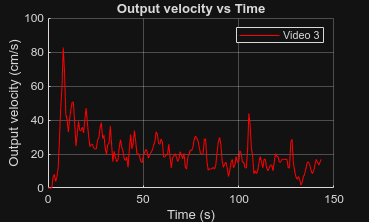

figure();
hold on;
plot(t3, vOut3, 'r-', 'DisplayName', 'Video 3');
title('Output velocity vs Time');
xlabel("Time (s)");
xlim([0,150]);
ylabel("Output velocity (cm/s)");
legend();
grid on;
hold off;

### Case 4

Water level velocity vs time

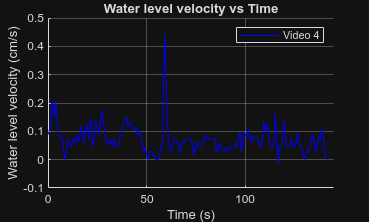

figure();
hold on;
plot(t4, vLevel4, 'b-', 'DisplayName', 'Video 4');
title('Water level velocity vs Time');
xlabel("Time (s)");
xlim([0,145]);
ylabel("Water level velocity (cm/s)");
legend();
grid on;
hold off;

Output velocity vs time

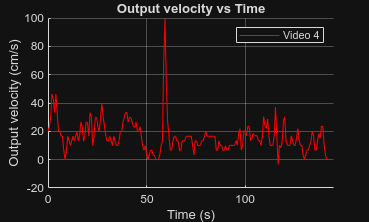

figure();
hold on;
plot(t4, vOut4, 'r-', 'DisplayName', 'Video 4');
title('Output velocity vs Time');
xlabel("Time (s)");
xlim([0,145]);
ylabel("Output velocity (cm/s)");
legend();
grid on;
hold off;

### Case 5

Water level velocity vs time

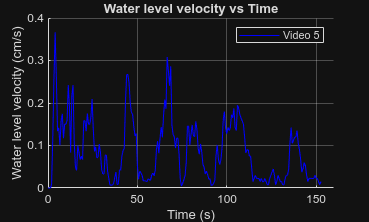

figure();
hold on;
plot(t5, vLevel5, 'b-', 'DisplayName', 'Video 5');
title('Water level velocity vs Time');
xlabel("Time (s)");
xlim([0,160]);
ylabel("Water level velocity (cm/s)");
legend();
grid on;
hold off;

Output velocity vs time

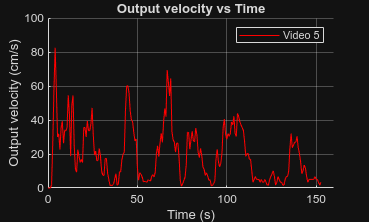

figure();
hold on;
plot(t5, vOut5, 'r-', 'DisplayName', 'Video 5');
title('Output velocity vs Time');
xlabel("Time (s)");
xlim([0,160]);
ylabel("Output velocity (cm/s)");
legend();
grid on;
hold off;